# AERO40003 Computing and Numerical Methods 1 

# Part 2: Numerical Methods 

# **Coursework 2024**

## Dr. Roderick Lubbock

## Completing this live file

You will submit only this self-contained completed livefile.No other scripts or other files will be marked. When completing this livefile:

- Please make sure all of your code is formatted as code using the "code" button on the Live Editor ribbon;

- Please make sure anything that is not code or code comments is formatted as text;

- Marks for each section and sub-section are shown in bold square brackets;

- Ensure that the entire livefile runs without errors or warnings before submitting! Sections of the file which do not run will not be marked.

#### Code

**EVERY LINE OF CODE (with the exception of plot commands and loop end statements) must have a comment clearly explaining what it does**. Comments should be brief but clear.

All self-contained functions must:

- be entered in the **Functions** section at the bottom of this livefile;

- be named correctly according to the guidance below;

- have a comment on each line of code explaining its function and **how it relates to the equations in the Class Slides or other theory;**

- NOT call built-in MATLAB functions from outside the standard MATLAB toolbox `C:\Program Files\MATLAB\R2022b``\toolbox\matlab` (but you may use these to check your functions).

To check the toolbox of a MATLAB function use the which command. The short name of the toolbox is shown after "**toolbox\**"  For example:

returns `C:\Program Files\MATLAB\R2022b\toolbox\``matlab``\polyfun\spline.m` which means it is in the standard MATLAB toolbox, whereas

returns `C:\Program Files\MATLAB\R2022b\toolbox\``curvefit``\curvefit\fit.m` which means it is in the curvefit toolbox, and not the standard MATLAB toolbox.

#### Plots

You should ensure any plots you are asked to produce have:

- axis labels;

- x and y grid;

- all lines/markers clearly differentiable through use of colour or line/marker type;

- legend (where more than one dataset is plotted), placed so as to minimise overlap with data lines/markes;

- any spaced discrete point data (such as that in the table below) plotted as points (not lines);

- when plotting overlapping functions use solid, dashed, chain-dashed and dotted linetypes to maximise visibility of all lines.

Note that any plots that are not formatted as above (and exemplified in the Computer Labs Code livefiles) **will not be marked.**

#### Numerical outputs

Anywhere you are asked to output values you should:

- Use one of the appropriate built-in MATLAB functions e.g. f`printf;`

- Include a clear description of what the output variable represents;

- Absolute errors should be presented to 3 significant figures.

### Submission

- You should submit your livefile on Blackboard by the deadline stated on Blackboard.

- Please rename the file in the format **NM1_2024_CW_XXXXXX.mlx where XXXXXX is your CID number.**

- As usual, please ensure you receive a confirmation email following submission. Only confirmed submitted files will be marked (partially complete Blackboard submissions will be ignored).

- **Note that submissions may be checked for plagiarism using multiple plagiarism detection softwares, including AI-based software designed specifically to detect the use of ChatGPT, Bard etc., as well as for similarity to other submissions. **

- **If you are trying to decide whether to plagiarise content or submit incomplete content, the choice should always be the latter, because ****a low grade is better than no grade****, and also avoids the stress (for you) and extra work (for departmental staff) involved in plagiarism investigations.**

## Introduction

*Bessel functions* describe electric fields, mechanical vibrations, heat conduction, optical diffraction and other phenomena involving cylindrical or spherical symmetry, for example the displacement of vibrating circular membranes, such as pressure transducer sensing elements and drum skins, as well as temperature distributions in heated cylindrical objects, such as combustor temperature probes and hot dogs in boiling water.  The image below (source:  [https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif](https://commons.wikimedia.org/wiki/File:Vibrating_drum_Bessel_function.gif) ) shows an animation of a vibrating drum skin. Everything you could possibly want to know about Bessel functions can be found at the [DLMF: NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/), which is based on a [famous mathemtical handbook](https://www.nist.gov/mathematics-statistics/handbook-mathematical-functions-abramowitz-and-stegun) known as "Abramowitz and Stegun", [available as a pdf here](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf).

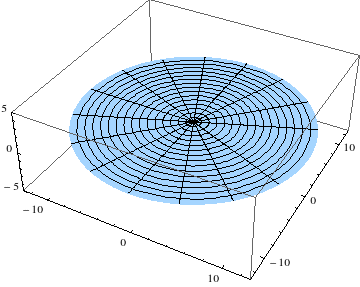

There are various different *kinds* of Bessel functions, including the *first kind *$J_n \left(x\right)$, the *second kind *$Y_n \left(x\right)$ and the *third kind *$H_n \left(x\right)$. For each kind there are also different orders, e.g. integers $n=0,1,2,3\ldotp \ldotp \ldotp$ The Bessel functions of the first kind for the first five integer orders (n = 0 to 4) are plotted below, using the built-in MATLAB function `besselj`. They look a bit like decaying sinusoids, except for some subtle differences as we shall see. 

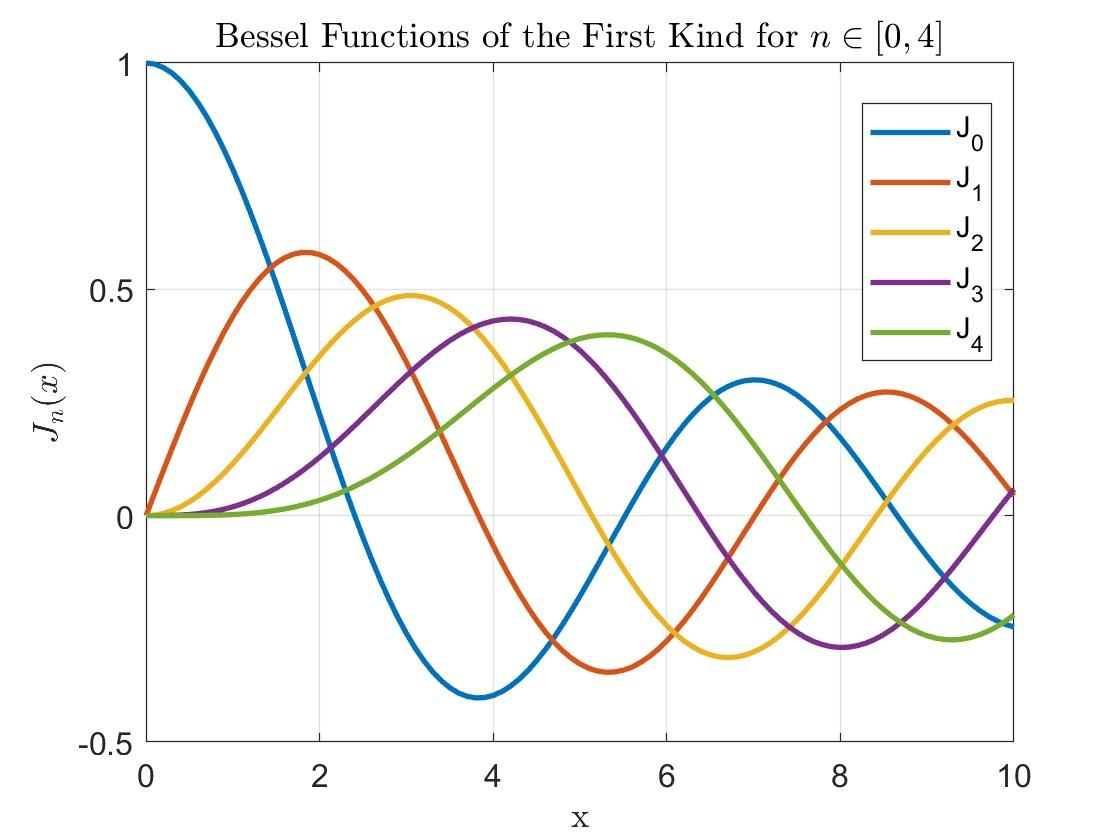

To see how this plot was made run the folllowing code:

Interestingly, the vertical displacement of the drumskin above is given by $u\left(r,\theta \right)=J_3 \left(r\right)\sin \left(3\theta \right)$ in polar coordinates. You should be able to see that, at a certain moment in time (e.g. at the limits of the motion), the vertical displacement plotted in the radial direction resembles $J_3$ in the plot above. You will learn how to obtain the full analytic solution to this sort of time-dependent differential equation later on in the undergraduate course.

**In this coursework you are going to investigate Bessel functions of the first kind, **$J_n \left(x\right)$**, over the interval **$0\le x \le 10$**.**

%INITIALIASE WORKSPACE
clc %clears comand widow
clf %clears figures
clear %clears workspace
close %closes
format long %formats long
%set default graph options
set(groot,'defaultLineLineWidth',2)  %sets graph line width as 2
set(groot,'defaultAxesFontSize',12)  %sets graph axes font size as 12
set(groot,'defaulttextfontsize',12)  %sets graph text font size as 12
set(groot,'defaultLineMarkerSize',12)%sets line marker size as 12
set(groot,'defaultAxesXGrid','on')   %sets X axis grid on 
set(groot,'defaultAxesYGrid','on')   %sets Y axis grid on
set(groot, 'DefaultAxesBox', 'on')   %sets Axes boxes on

## Part 1: Interpolation [7 marks]

Bessel functions are usually not amenable to straightforward evaluation (e.g. by hand or with a standard scientific calculator) and are often compiled in standard mathematical tables. One such table is shown below:

`0             0`

`0.5       0.24227`

`  1       0.44005`

`1.5       0.55794`

`  2       0.57672`

`2.5       0.49709`

`  3       0.33906`

`3.5       0.13738`

`  4     -0.066043`

`4.5      -0.23106`

`  5      -0.32758`

`5.5      -0.34144`

`  6      -0.27668`

`6.5      -0.15384`

`  7    -0.0046828`

`7.5       0.13525`

`  8       0.23464`

`8.5       0.27312`

`  9       0.24531`

`9.5       0.16126`

` 10      0.043473`

%converting example queary points into table format with named collumns
BesselDataPoints = array2table([...
  0             0
0.5       0.24227
  1       0.44005
1.5       0.55794
  2       0.57672
2.5       0.49709
  3       0.33906
3.5       0.13738
  4     -0.066043
4.5      -0.23106
  5      -0.32758
5.5      -0.34144
  6      -0.27668
6.5      -0.15384
  7    -0.0046828
7.5       0.13525
  8       0.23464
8.5       0.27312
  9       0.24531
9.5       0.16126
 10      0.043473...
     ], "VariableNames",["X","J(x)"]);

Investigate the different methods of interpolation covered in the course using the interpolant data in the above table as follows:

- **M1.1:** Write a self-contained MATLAB function **called IntPoly** that fits a polynomial of the maximum possible order to the tabular data using the first approach in Class 4 involving inversion of a matrix of $x$-values. **[0.5]**

- **M1.2:** Write a self-contained MATLAB function **called LagrangePoly** to compute the interpolating Lagrange polynomial that passes through all inerpolant data points. **[0.5]**

- **M1.3:** Write a self-contained MATLAB function **called IntSpline** that performs cubic spline interpolation with natural (free-runout) end conditions. **[0.5]**

- **M1.4: **Using the function from M1.1 interpolate data sampled directly from `besselj `with the same number of points as the original data (i.e. 21), but using Chebyshev spacing. **[0.5]**

All functions should:

- take as input a vector of query points that is evenly spread across the interval and spaced by 0.1

- output the evaluation of the interpolation function at the query points.

- NOT use any MATLAB built-in functions.

Evaluate the performance of your self-contained functions as follows:

- **E1.1:** Plot the interpolated data (as a continuous curve) alongside the tabular data (as points) for all methods on a single plot. **[1]**

- **E1.2:** Evaluate and plot the absolute error in the interpolation compared to `besselj`. Plot the absolute error as a function of $x$ for all methods M1.1 to M1.4 on a single plot. **[1]**

### Questions

- **Q1.1:** How does the performance of the various methods compare in terms of accuracy and computation time? You should compute and output the time required to perform the interpolation along with the $L_2$-norm of the absolute error across the interval using e.g. `sprintf` (as in the Computer Lab Codes) to clearly state which values relate to which method.  **[1]**

- **Q1.2:** Methods 1. and 2. should generate equivalent (i.e. the same) polynomials according to Class 4. Explain with evidence whether or not this is the case.  **[1]**

- **Q1.3:** Compare method 3. with the built-in MATLAB function `spline`. Are the outputs the same? Explain any discrepancies. **[1]**

### Hints

**Method M1.2:** You should use a for loop to step through the product in the basis functions and another for loop to sum the scaled basis fuctions to get the Lagrange polynomial.

### Part 1: Your Solution

%converts table data type to array for given bessel data 
BesselData = table2array(BesselDataPoints);
%generates a n array between 0 and 10 with 100 points;
x = linspace(0,10,100);

%starts timer to record time elapsed
tic
%stores interpolated y values form function IntPoly  
intepolatedY = polyval(IntPoly(BesselData),x);

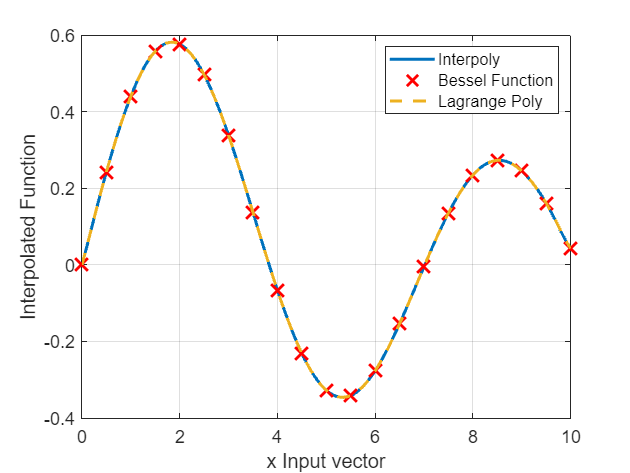

%stores the elapsed time to Varibale intPolyTime 
intPolyTime = toc;

%starts timer
tic 
%Calls LagrangePoly funtion and stures in array lagrangeY
lagrangeY = LagrangePoly(BesselData,x);
%stores elapsed time to variable lagrangeTime
lagrangeTime = toc;

%tic 
%splineY = IntSpline(BesselData,x)
%splineTime = toc

%plots interpolated values from IntPoly
plot(x,intepolatedY);
%holds plot on 
hold on 
%plots original bessel point from data set
plot(BesselData(:,1),BesselData(:,2),"x","Color","red");
%holds plot on
hold on
%plots interpolated values from LagrangePoly
plot(x,lagrangeY,"--")
%holds plot on 
hold on
%plots spline intepolated points
%plot(x,splineY,";");
%holds plots on 
%hold on

%adds xlabel
xlabel("x Input vector")
%adds ylabel
ylabel("Interpolated Function")
%adds legend ont plot
legend("Interpoly",'Bessel Function','Lagrange Poly')
%adds grid lines
grid on
%turns hold off
hold off

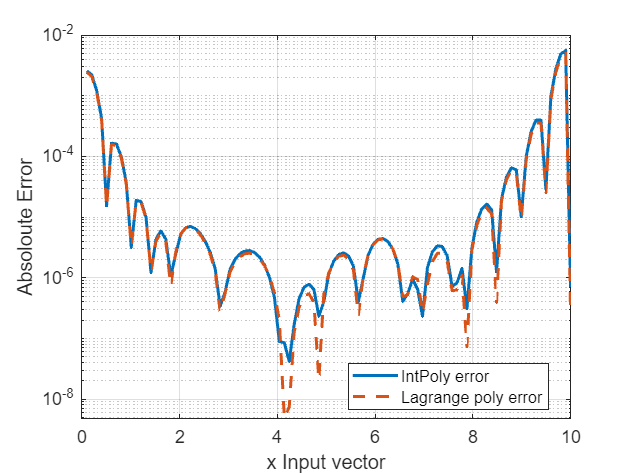

%finds actual Bessel J funtion points for 1st order
bessel = besselj(1,x);
%calculates the absoulte error for IntPoly
IntPolyerror = abs(intepolatedY-bessel);
%calculates the absolute error for Lagrange
Lagrangeerror = abs(lagrangeY-bessel);
%calculates the spline errors
%errorSpline = abs(SplineY-bessel);

%creates a new figure
figure;

%plots partial log plot
semilogy(x,IntPolyerror);
%holds on
hold on
%plots partial log plot
semilogy(x,Lagrangeerror,"--");
%holds on 
hold on
%plots partial log plot
%semilogy(x,errorSpline);

%adds the legend onto the plot
legend('IntPoly error','Lagrange poly error',Location='best');
%adds the xlabel
xlabel('x Input vector');
%adds the ylabel
ylabel('Absoloute Error');
%adds grid on
grid on 
%holds off
hold off

%Calculating norm for intpoly
nIntpoly = norm(IntPolyerror- x,2);
%Calculating L2 norm for lagrange poly
nlagrange = norm(Lagrangeerror-x,2);
%outputs the IntPoly comutation results in structred string
sprintf('Intpoly had a comutation time of %d s and a L2 norm of %d',intPolyTime,nIntpoly)

ans = 'Intpoly had a comutation time of 1.983350e-02 s and a L2 norm of 5.787798e+01'

%outputs the LagrangePoly comutation results in structred string
sprintf('Lagrange polynomial had a computation time of %d s and a L2 norm of %d',lagrangeTime,nlagrange)

ans = 'Lagrange polynomial had a computation time of 4.136830e-02 s and a L2 norm of 5.787825e+01'

Enter explanation here.

Q1.1: The quickest interpolation method was using the matrix inversion method to fit to the maximum order polynomial whick took the least computation time compared to the lagrange polynomial method which took the longest computation time. However the lagrange polynomial had the highest accuracy which is shown in the absolute error plots  

Q1.2: M1.1 and M1.2 produce similar polynomial expressions to the expected polynomilas in the handout. But due to rounding errors in the computaion the polynomials may not be identical. This is likely due to the discrete nature of the matlab functions where the code aproximates the functions for a input vector array  so the polynomials are not identical. 

## Part 2: Numerical Integration [7 marks]

For integer values of $n$, the bessel function of the first kind may be defined in integral form using *Bessel's integrals* as:


$$J_n(x) = \frac{1}{\pi} \int_0^\pi \cos(n\tau-x\sin\tau)d\tau$$


Investigate the different methods of numerical integration covered in the course to evaluate Bessel's integral for the **first order** Bessel Function of the first kind, $J_1 \left(x\right)$ as follows:

- **M2.1:** Write a self-contained MATLAB function **called trapzJ1** that uses the Trapezium rule. **[0.5]**

- **M2.2:** Write a self-contained MATLAB function** called simpsonJ1** that uses Simpson's 1/3 rule. **[0.5]**

- **M2.3:** Write a self-contained MATLAB function **called gaussJ1** that uses Gauss-Legendre quadrature. **[2]**

All functions should: 

- take as input a vector $x$ that is evenly spread across the interval and spaced by 0.1, as well as the number of points used in the integration, *N*.

- output $J_1 \left(x\right)$. 

You should evaluate the performance of your self-contained functions as follows:

- **E2.1:** Plot the approximated function alongside values computed using `besselj` as a function of $x$ for all methods on a single figure. **[0.5]**

- **E2.2:** Evaluate and plot the absolute error compared to `besselj `as a function of $x$ for all methods on a single figure. You may wish to make the ordinate axis logarithmic for clarity.**[0.5]**

- **E2.3:** On a single figure, plot the average absolute error across the interval vs the number of points, *N*, used in the integration for each method for a sensible range of *N*. Plot a horizontal line representing double-precision accuracy (machine epsilon), and for each method work out how many points are required to evaluate $J_1 \left(x\right)$ to within machine (double) precision of `besselj`. You may wish to make the ordinate axis logarithmic for clarity. **[0.5]**

- **E2.4:** Write a simple loop to evaluate the integral for the vector $x$ using the built-in MATLAB function `integral. `Plot the error across the interval and evaluate the computation time required to achieve double-precision accuracy. **[0.5]**

### Questions

- **Q2.1:**  How does the computation time of the three methods M2.1,M2.2, M2.3 and the looped `integral `function compare? Do you think the function `besselj` uses numerical integration to evaluate Bessel functions? **[1]**

- **Q2.2: **You should notice that for some values of $x$ for some methods the absolute error is exactly zero. Explain with reasoning whether or not these zero-error values are correct. **[1]**

### Hints

**Method M2.1**: Use the built-in MATLAB function` trapz`.

**Method M2.2:** Use an anonymous function (as in the Computer Lab Codes), that takes x and tau as the inputs, in order to define the integrand.

**Method M2.3**: You will need to evaluate the Legendre polynomials to higher orders than in the Class slides. 

One way to approach this is to use the MATLAB functions conv and polyder to evaluate the definition of$L_N \left(x\right)$ in Class 3:


$$L_N(x) =\frac{1}{2^NN!} \frac{d^N}{dx^N}(x^2-1)^N$$


The $(x^2-1)^N$term can be evaluated using the built-in MATLAB function `conv,` which multiplies two polynomials and returns the coefficients of the resulting polynomial (a process known as convolution):

The coefficients of the derivative of a polynomial can be found using built-in MATLAB function `polyder`. You will need to code a loop similar to the one for `conv` to calculate the *N*th derivative. Yo can also use `polyder` and `polyval` to evaluate the weights.

To obtain the roots of the polynomial based on the coefficient simply use the built-in MATLAB function `roots`. To evaluate a polynomial for a given vector of input values simply use the built-in MATLAB function `polyval`.

Another way to generate the Legendre polynomials is using Bonnet's recursion formula:


$$(N+1)L_{N+1}(x) = (2N+1)xL_N(x)-NL_{N-1}(x)$$


Starting with $L_0 \left(x\right)=1$ and $L_1 \left(x\right)=x$ this allows all subsequent polynomials to be computed. For example, $L_2 \left(x\right)$ is found from:

$L_2(x) =\frac{1}{2} \left(3xL_1(x)-L_0(x)\right) = \frac{1}{2} \left(3x^2-1\right) $.

Based on this it is possible to code a recurrence relation to calculate the ceofficients of any Legendre polynomial. To illustrate this consider the coefficients of the first few polynomials:


$$L_0(x) = 1: $$



$$L_1(x)=x:$$



$$L_2(x) = \frac{1}{2} \left(3x^2-1\right) :$$


You should be able to spot a pattern forming that corresponds to Bonnet's recursion formula. Obviously you will need to use a loop and work out how to increment the number of coefficients for each iteration. You can check your polynomials against the symbolic math toolbox function `legendreP.`

### Part 2: Your Solution

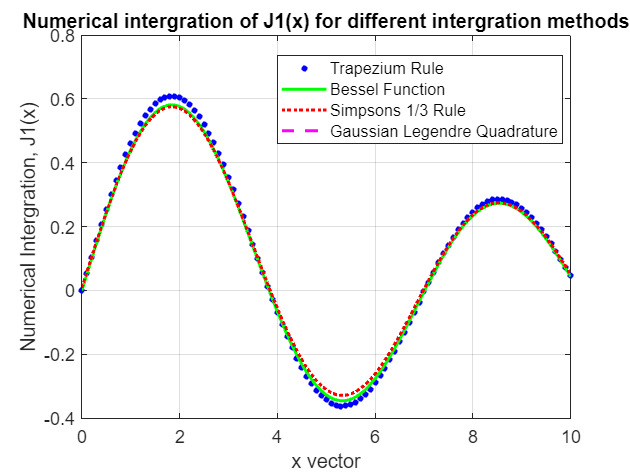

%initialises the x vals
x = 0:0.1:10;
%initialses the Number of points
N = 40;

%stores the output of trapzJ1 in trap
trap = trapzJ1(x,N);
%stores the output of simpsonJ1 in simpsons
simpsons = simpsonJ1(x,N);
%stores the output of gaussJ1 in gauss
gauss = gaussJ1(x,N);
%defines the actual Bessel data points
bessel = besselj(1,x);

%creates new figure
figure;
%plots trpaezium values
plot(x,trap,'.','Color','b')
%holds on
hold on 
%plots bessel funtion
plot(x,bessel,'color','g')
%holds on 
hold on
%plots simpsons values
plot(x,simpsons,':','Color','r')
%holds on
hold on
%plots gauss values
plot(x,gauss,'--','color','m'); %%%%%%%%%%%%%%%%%%%%%%%%%%%

%adds legend
legend('Trapezium Rule','Bessel Function','Simpsons 1/3 Rule','Gaussian Legendre Quadrature',Location='best');
%adds title
title("Numerical intergration of J1(x) for different intergration methods")
%adds xlabel
xlabel("x vector")
%adds ylabel
ylabel("Numerical Intergration, J1(x)")
%turns grid on
grid on
%holds off
hold off

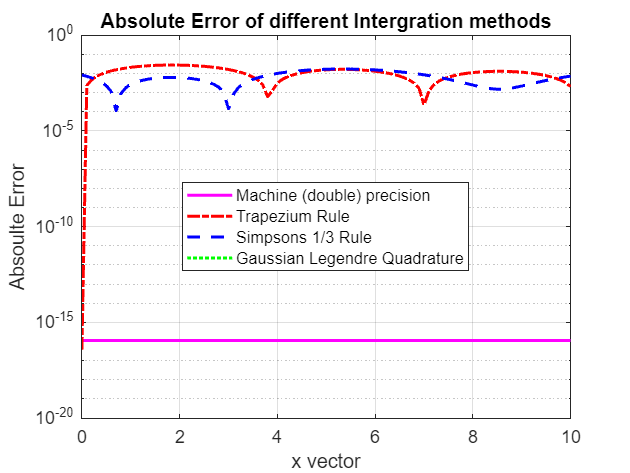

%stores absoulte error of trapezium
TrapeziumError = abs(bessel - trap);
%stores absoulte error of simpsons
SimpsonError = abs(bessel - simpsons);
%stores absoulute error of gauss
GaussError = abs(bessel - gauss);
%stores double precision value
doubleprecisionaccuracy = ones(size(x)).*(2^(-53));

%creates new figure
figure;
%plots partial log plot
semilogy(x,doubleprecisionaccuracy,'Color','m',LineStyle='-');
%plots partial log plot
hold on
%plots partial log plot
semilogy(x,TrapeziumError,'Color','r',LineStyle='-.')
%plots partial log plot
hold on
%plots partial log plot
semilogy(x,SimpsonError,'color','b',LineStyle='--');
%plots partial log plot
hold on 
%plots partial log plot
semilogy(x,GaussError,'Color','g',LineStyle=':'); %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%adds title 
title("Absolute Error of different Intergration methods")
%adds legend
legend('Machine (double) precision','Trapezium Rule','Simpsons 1/3 Rule','Gaussian Legendre Quadrature', Location='best');
%adds xlabel
xlabel('x vector');  
%adds ylabel
ylabel('Absoulte Error');
%adds grid on 
grid on
%holds off
hold off

Enter explanation here.

## Part 3: Function Roots [6 marks]

Investigate the different methods of root finding covered in the course to find all of the roots on the interval for the **zeroth order** Bessel function of the first kind, $J_0 \left(x\right)$, as follows:

- **M3.1:** Write a self-contained MATLAB function **called fzeroJ** that uses the built-in MATLAB function `fzero`. **[0.5]**

- **M3.2:** Write a self-contained MATLAB function **called bisectionJ** that uses the bisection method. **[0.5]**

- **M3.3: **Write a self-contained MATLAB function **called newtonJ** that uses Newton's method. **[0.5]**

- **M3.4: **Write a self-contained MATLAB function **called secantJ** that uses the Secant method. **[0.5]**

All functions should: 

- take as input the order of the Bessel function and the start and end points of the interval (i.e. [0 10]).

- output the roots to a tolerance of** 1e-10** (in other words stop iterating when the solution is changing by less than the tolerance), if this is possible within a computation time of say 10 minutes (use Ctrl+C or Command+. to stop the computation if not).

- NOT use predetermined search intervals, but rather determine these from the function itself (so that in principle your code would function for any order/kind of Bessel function and/or outside the interval). 

- all use the same method for determining the search interval.

You should evaluate the performance of your self-contained functions as follows:

- **E3.1:** Plot the approximated roots alongside the function evaluated using `besselj`, using a different plot for each method. **[1]**

- **E3.2:** Compute and output the time required to compute all roots on the interval using e.g. f`printf` to clearly state which values relate to which method. Also compute the average relative error for the three roots on the interval 0,10 compared to the values in  [Abramowitz and Stegun](https://s3.amazonaws.com/nrbook.com/AandS-a4-v1-2.pdf). **[1]**

### Questions

- **Q3.1:** How do the various methods compare in terms of accuracy and computation time? Which method is best? **[1]**

- **Q3.2:** Does your function work for other orders of the Bessel function of the first kind, $J_0 \left(x\right)$, and/or for roots outside the interval (i.e. $x>10$)? If so, when does it stop working and why? How would you need to modify your code to get it to work? N.B. you should not try to modify your function to get it to work on other functions or outside the interval, but you should only try to understand (and explain) why it doesn't work. **[1]**

### Hints

One way to find the search interval is to start from the origin and find the first data point where the sign has changed, then search between that point and the next. You can then continue this to the next root.

**Method 3.3:** You will need to work out the derivative. This can be found from the series definition of the function, and you can also look it up at [DLMF: §10.6 Recurrence Relations and Derivatives ‣ Bessel and Hankel Functions ‣ Chapter 10 Bessel Functions (nist.gov)](https://dlmf.nist.gov/10.6).

### Part 3: Your Solution

%defineds upper linit to intergration
upperlim = 10;
%defines lower limit to intergration
lowerlim = 0;
%difines order of Bessel funtion
order = 0;
%defines array for roots of Zeroth order Bessel funtion from liruriture
%values
AbramowitzandStegun = [2.404825577,5.5200781103,8.6537279129]; %%sig fig 
%defines display format for fprintf outputs
displayformat = 'Reletive errors for roots using %s method, in defined interval with respect to Abramowitz and Stegun\n %30.30f %30.30f %30.30f'

displayformat = 'Reletive errors for roots using %s method, in defined interval with respect to Abramowitz and Stegun\n %30.30f %30.30f %30.30f'

%starts timer
tic
%stores output of fzeroJ into array roots
roots = fzeroJ(order,lowerlim,upperlim);
%stores computation time into variable rootstime
rootstime = toc;
%calculates absolute reletive error
rootserror = abs(AbramowitzandStegun-roots);
%displays outputs with regards to format defined in displayformat string
fprintf(displayformat,"Roots",rootserror)

Reletive errors for roots using Roots method, in defined interval with respect to Abramowitz and Stegun
 0.000000019304227549810093478300 0.000000000013689493982838030206 0.000000000011011636047442152631

%starts timer
tic
%stores output of newtonJ into array roots
newtonroots = newtonJ(order,lowerlim,upperlim);
%stores computation time into variable rootstime
newtonwtime = toc;
%calculates absolute reletive error

%newtonerror =  abs(AbramowitzandStegun- newtonroots); %commented to remove
%errors from run thorugh
%displays outputs with regards to format defined in displayformat string
%fprintf(displayformat,'Newtons',newtonerror)


%starts timer
tic
%stores output of newtonJ into array roots
secantroots = secantJ(order,lowerlim,upperlim);
%stores computation time into variable rootstime
secanttime = toc;
%calculates absolute reletive error
secanterror = abs(AbramowitzandStegun - secantroots);
%displays outputs with regards to format defined in displayformat string
fprintf(displayformat,'Secant',secanterror)

Reletive errors for roots using Secant method, in defined interval with respect to Abramowitz and Stegun
 0.000000019304227549810093478300 0.000000000013689493982838030206 0.000000000011011636047442152631

%starts timer
tic 
%stores output of newtonJ into array roots
bisectionroots = bisectionJ(order,lowerlim,upperlim);
%stores computation time into variable rootstime
bisectiontime = toc;
%calculates absolute reletive error
bisectionerror = abs(AbramowitzandStegun - bisectionroots);
%displays outputs with regards to format defined in displayformat string
fprintf(displayformat,'Bisection',bisectionerror)

Reletive errors for roots using Bisection method, in defined interval with respect to Abramowitz and Stegun
 0.182603354842453047268691079807 0.000000000040463632444698305335 0.000000000051496584774213260971

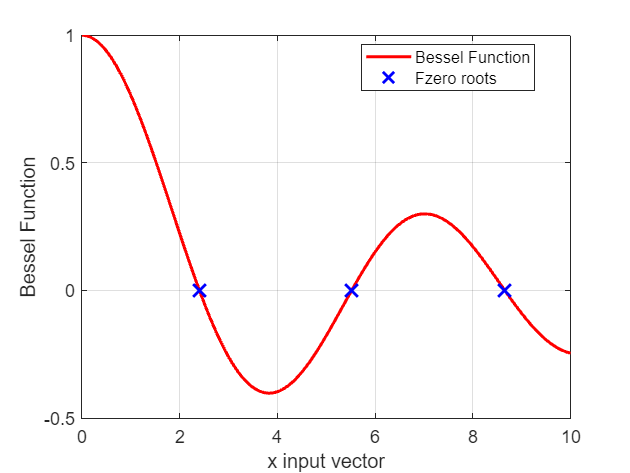

%creates x input vector with 100 equally spaced data points 
x = linspace(0,10,100);
%stores the roots from the zeros function 
y = zeros(size(roots,1));
%calls and stores besselJ0 funtion points into array bessel for plotting 
bessel = besselj(0,x);

%creates a new figure
figure;
%plots Bessel funtion line 
plot(x,bessel,'Color','r')

%holds plot
hold on
%plots roots from fzero
plot(roots,y,'x','Color','b')
%adds legend to plot
legend('Bessel Function','Fzero roots',Location='best')

%add x axis label
xlabel('x input vector')
%add y axis label
ylabel('Bessel Function')
%turns grid on
grid on
%stops changes to figures
hold off

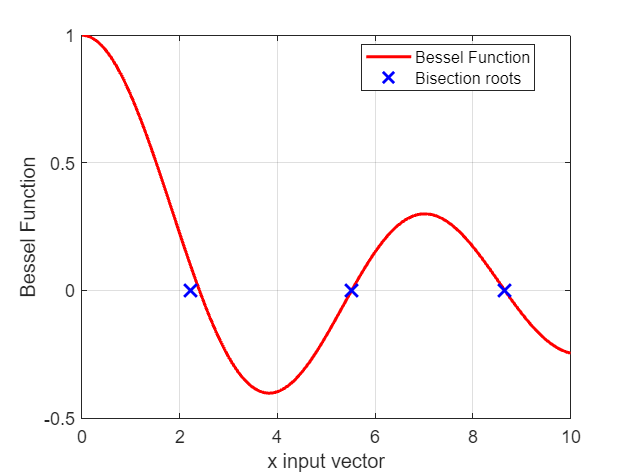

%creates a new figure
figure;
%plots Bessel funtion line 
plot(x,bessel,'Color','r')
%holds plot
hold on
%plots roots from Bisection method
plot(bisectionroots,y,'x','Color','b')
%adds legend to plot
legend('Bessel Function','Bisection roots',Location='best')
%add x axis label
xlabel('x input vector')
%add y axis label
ylabel('Bessel Function')
%turns grid on
grid on
%stops changes to figures
hold off

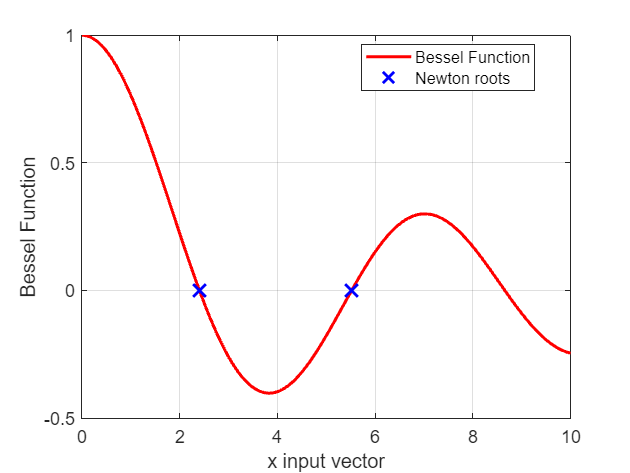

%creates a new figure
figure;
%plots Bessel funtion line 
plot(x,bessel,Color='r')
%holds plot
hold on
%plots roots from Bisection method
plot(newtonroots,y,'x','Color','b')
%adds legend to plot
legend('Bessel Function','Newton roots', Location='best')
%add x axis label
xlabel('x input vector')
%add y axis label
ylabel('Bessel Function')
%turns grid on
grid on
%stops changes to figures
hold off

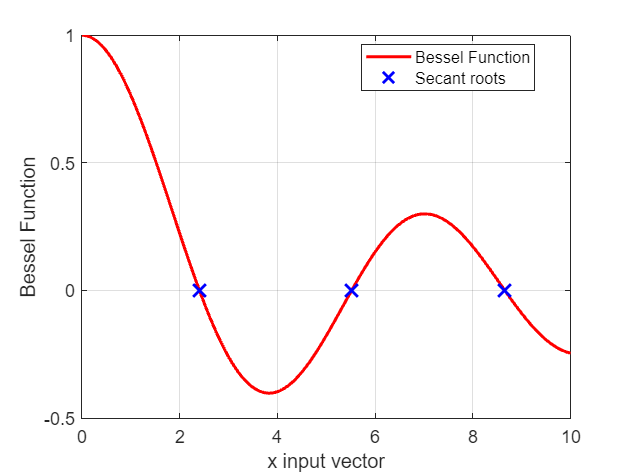

%creates a new figure
figure;
%plots Bessel funtion line 
plot(x,bessel,'color','r')
%holds plot
hold on
%plots roots from Bisection method
plot(secantroots,y,'x','Color','b')
%adds legend to plot
legend('Bessel Function','Secant roots',Location='best')
%add x axis label
xlabel('x input vector')
%add y axis label
ylabel('Bessel Function')
%turns grid on
grid on
%stops changes to figures
hold off

Enter explanation here.

Q3.1: The methods with the highest accuracy was the newton and secant methods as the absolute error for the two was lowest compared to the real bessel function roots produced by the fzero function. In terms of computation time the bisection method was fastest as no derivitived were needed to be evaluated compared tothe computationally expensive newtons method witch was the slowest to converge. The bisection method howeveer was the least accurate. 

### Your Functions

#### Part 1:

function interpolated_coeffs = IntPoly(DataPoints)
%defines Function IntPoly to interpolate input data points using an
%polynomial of maximum order

%stores x values from the datapoints array from the first collumn
x_vals = DataPoints(:,1);
%stores y values from the datapoints array from the second collumn
y_vals = DataPoints(:,2);

%initialises N as the max polynomial power
N = (size(x_vals, 1)-1);
%initialises posible powers of polynomial 
pwr = 0:(N);
%generates square array for all terms of the polynomial
A = ones(N+1,N+1);
%multiplies array by x values for each interpolation point
M = A.*x_vals;
%raises apropriate collumns to power of of position in array to form array
%of powers of x
M = M.^(pwr);
%evaluated power array 
interpolated_coeffs = flip((M\y_vals)');

end

function interpolated_vals = LagrangePoly(DataPoints , x_quearypoints)
%defines Function LagrangePoly to interpolate input data points

%stores x values from the datapoints array from the first collumn
x_vals = DataPoints(:,1);
%stores y values from the datapoints array from the second collumn
y_vals = DataPoints(:,2);

%loops through all x_vals
for i = 1:length(x_vals)
    %loops thorugh all queary points
    for k = 1:size(x_quearypoints,2)
        %defines the denominator value
        denominator = x_vals(i)-x_vals;
        %defines the numerator values
        numerator = (-x_vals)+(x_quearypoints(k))';
        %intiialising denominator
        denominator(i) = [];
        %initialises numerator
        numerator(i) = [];
        %calculates  basis polynomial values 
        basis_poly(i,k) = y_vals(i,:)*(prod(numerator)/prod(denominator));
        %sums up all basis polynomial values
        interpolated_vals(:,k) = sum(basis_poly(:,k));
    end
end

end

function interpolated_vals = IntSpline(DataPoints, quearypoints)
%defines Function IntSpline to interpolate input data points

%stores x values from the datapoints array from the first collumn
x_vals = DataPoints(:,1);
%stores y values from the datapoints array from the second collumn
y_vals = DataPoints(:,2);

%predefines a adiference
difference = 1/2;

%loops through all values in x_vals
for i = 0:(size(x_vals,1)-3)
    %hhhjhhhh
    z(i+1,:) = (y_vals(i+3)-2*y_vals(i+2)+y_vals(i+1))/(1/4);
end

%sets dimentions = 19
dim = 19;
%sets elements as dim^2
elements = dim^2;
%initialises M as zeros
M = zeros(dim);

%sets some M values to coeficients for multiplication 
M(1:dim+1:elements) = 4*(1/6);
%sets some M values to coeficients for multiplication
M(2:dim+1:elements) = 1*(1/6);
%sets some M values to coeficients for multiplication
M(20:dim+1:elements) = 1*(1/6);

%calucuales the Y values
YY = M\z;

%transposes the martix of queary points for multiplication
quearypoints = quearypoints';

%loops through all x_vals
for i = 2:(size(x_vals,1)-1)
    %loops through all queary points
    for j = 1:size(quearypoints,1)
        %part of interated formula
        interpolated_vals(i,j) = (YY(:,i)/6);
        %part of interated formula
        interpolated_vals(i,j) = interpolated_vals(i,j)*((((x_vals(i+1)-quearypoints(j))^3)/(x_vals(i+1)-x_vals(i))-(x_vals(i+1)-x_vals(i))));
        %part of interated formula
        interpolated_vals(i,j) = interpolated_vals(i,j)*(x_vals(i+1)-quearypoints(j))+(YY(:,i+1)/6);
        %part of interated formula
        interpolated_vals(i,j) = interpolated_vals(i,j)*((((quearypoints(j)-x_vals(i))^3)/(x_vals(i+1)-x_vals(i))-(x_vals(i+1)-x_vals(i))));
        %part of interated formula
        interpolated_vals(i,j) = interpolated_vals(i,j)*(quearypoints(j)-x_vals(i))+y_vals(i)*(x_vals(i+1)-quearypoints(j));
        %part of interated formula
        interpolated_vals(i,j) = interpolated_vals(i,j)/((x_vals(i+1)-x_vals(i)))+y_vals(i+1)*((quearypoints(j)-(i))/(x_vals(i+1)-x_vals(i)));
    end
end
end

#### Part 2:

function J1 = trapzJ1(x_vals,N)
%defines function for inergration using trapezium method

%initialises array J1 as zeros
J1 = zeros(1,size(x_vals,2));
%intiialises t values as a evenly spaced array
t_vals = linspace(0,pi,N);
%initialises y values as zeros
y_vals = zeros(size(x_vals,2),size(t_vals,2));

%itterates through all xvals
for i = 1:size(x_vals,2)
    %calcuklates the function values
    A = t_vals - x_vals(i)*sin(t_vals);
    %calcuklates the function values
    y_vals(i,:) = cos(A);
    %calcuklates the function values
    J1(i) = trapz(t_vals, y_vals(i,:));
end
%divedes by 3
J1 = J1/3;
end

function J1 = simpsonJ1(x_vals,N)
%defines function for inergration using simpson method

%intiialises t values as a evenly spaced array
t_vals = linspace(0,pi,N);
%define h for interval
h = (pi)/N;

%itterates through x_vals
for i = 1:size(x_vals,2)
    %itterates though all tvalues
    for j = 1:size(t_vals,1)
        %finds function values for odd tvalues
        f_odd = cos(t_vals(:,(3:2:end-1)) - x_vals(i)*sin(t_vals(:,(3:2:end-1))));
        %finds function values for even tvalues
        f_even = cos(t_vals(:,(2:2:end-2))- x_vals(i)*sin(t_vals(:,(2:2:end-2))));
        %finds function values for 0th value
        f_0 = cos(t_vals(1) - x_vals(i)*sin(t_vals(1)));
        %finds function values for last values
        f_end = cos(t_vals(end - x_vals(i)*sin(t_vals(end))));
        %uses final trapezium rule formula
        J1(i) = (h/(3*pi))*(f_0+sum(2*f_odd)+sum(4*f_even)+f_end);

    end
end
end

function J1 = gaussJ1(x_vals,N)
%defines function for inergration using gaussian legendre method

%initialises coeficients
coeffs = [1,0,-1];
%initialises polynomial order
polynomialorder = 1;
%itterates through the N values
for i =1:N
    %finds convolution of the polynomial orders and coeffs
    polynomialorder = conv(polynomialorder,coeffs);
end

%finds derivirtives
derivitives = polynomialorder;
%loops thought N values
for i = 1:N
    %finds derivitives using polyder 
    derivitives = polyder(derivitives);
end

%finds legendre poly
legendre_polynomial = ((1./(2^N*factorial(N)))*derivitives);
%finds quadrature points
quad_points = roots(legendre_polynomial)';

%loops throigh all quadrature points
for i = 1:size(quad_points,2)
    %finds intermediate variable A
    A = 2/(1-quad_points(i)^2);
    %finds intermediate variable C
    C = (1/(2^N*factorial((N))));
    %finds intermediate variable B
    B = polyval(derivitives*polyder(C),quad_points(i))^(-2);
    %finds the weights of the array 
    weights(i) = A*B;
end

%loops thoiugh all x values
for i = 1:size(x_vals,2)
    %loops through all N values
    for j = 1:N
        %finds all t_values
        t_vals = (pi*(1/2)*(1+quad_points(j)));
        %finds intergrand
        integrand = cos(t_vals-x_vals*sin(t_vals));
        %finds interpolation values
        interpol(:,j) = weights(j)*integrand;
    end
    %finds sum of intergrated polynomial 
    J1(i) = sum(interpol(i,:));
end
%divides by 2
J1 = J1*(1/2);
end

#### Part3:

function roots = fzeroJ(n,lowerlim,upperlim)
%finds roots ufing zero function in matlab

%defines the besselJ function
BesselJ = @(x_vals) besselj(n,x_vals);
%finds the interval
range = linspace(lowerlim,upperlim,10);
%initialises the roots
roots = [];
%loops for the interval
for i = 1:size(range,2)
    %checks if sighn changes
    if BesselJ(i)*BesselJ(i+1)<0
        %adds roots to final output array
        roots(end+1) = fzero(BesselJ,range(i));
    end
end
end

function roots = bisectionJ(n,lowerlim,upperlim)
%finds roots using bisection method

%defines tge besselJ function
BesselJ = @(x_vals) besselj(n,x_vals);
%finds interval
range = linspace(lowerlim,upperlim,10);
%initialises the roots
roots = [];
%loops though all interval
for i = 1:(size(range,2)-1)
    %checks if sign changes
    if BesselJ(i)*BesselJ(i+1)<0
        %initialise the difference as 100
        dif = 100;
        %sets the tolerance
        tol = 1e-10;
        %sets the x0 from the intervals
        x0 = range(i);
        %sets the x1 from intervals
        x1 = range(i+1);
        
        %sets the temporary roots
        temp_root = [];
        %loops till tollerence value is met
        while abs(dif)> tol
            %finds midpoint
            x_mid = 0.5*(x0+x1);
            %check if sighn changes
            if BesselJ(x_mid)*BesselJ(i)<0
                %redefines x1
                x1=x_mid;
                %finds difference
                dif = abs(x0-x_mid);
            else
                %finds the difference
                dif = abs(x0-x_mid);
                %redefines x0
                x0 = x_mid;
            end
            %stores xmid in temporary roots
            temp_root(i) = x_mid;
        end
        %adds to the roots output array
        roots(1+end) = temp_root(i);
    end
end
end

function roots = newtonJ(n,lowerlim,upperlim)
%finds roots using the newton method

%initialises the function for bessel
BesselJ = @(x_vals) besselj(n,x_vals);
%initialises interval
range = linspace(lowerlim,upperlim,10);
%initialises roots
roots = [];

%loops through interval
for i =1:size(range,2)
    %checks sign
    if BesselJ(i)*BesselJ(i+1)<0
        %defines x0
        x0 = range(i);
        %defines the difference
        dif = 100;
        %defines the tollerence
        tol = 1e-10;

        %loops thorugh till the tollerence is met
        while abs(dif)>tol
            %finds x1
            x1 = x0 - BesselJ(x0)*((0.5*(BesselJ(i-1)-BesselJ(i+1)))^-1);
            %finds difference
            dif = abs(x1-x0);
            %finds x0
            x0 = x1;
        end
        %checks in range
        if (x0<=upperlim)&&(x0>=lowerlim)
            %adds to roots output
            roots(1+end) = x0;
        end
    end
end
end

function roots = secantJ(n, lowerlim,upperlim)
%finds roots using secant method

%initilalises the bessel J function
BesselJ = @(x_vals) besselj(n,x_vals);
%initiialises the interval
range = linspace(lowerlim,upperlim,10);
%initialises the roots array
roots = [];
%loops through all range
for i =1:size(range,2)-1
    %checks the sighn
    if BesselJ(i)*BesselJ(i+1)<0
        %finds x0
        x0 = range(i);
        %finds x1
        x1 = range(i+1);
        %initilalises difference
        dif = 100;
        %initialises the tollerence
        tol = 1e-10;

        %loops till diffence is done
        while abs(dif)>tol
            %finds the aproximate gradient
            differencefraction = (x1-x0)/(BesselJ(x1)-BesselJ(x0));
            %redefines x2
            x2 = x1 - BesselJ(x1)*differencefraction;
            %redefines difference
            dif = x2 - x1;
            %redefines x0
            x0 = x1;
            %redefines x1
            x1 = x2;
        end
        %checks if root is in range
        if x1<=upperlim && x1>=lowerlim
            %adds the root ti the output array
            roots(end+1) = x1;
        end
    end
end
end